# ***Εργασία 2024 (REPORT)***

### *Χρήστος Λεβαντής, 321-2020110*

% Γενικά, τα script έχουνε σχόλια, Οπότε δεν γράφω πολλές 
% περιγραφές στην αναφορά γιατί θεωρώ είναι καλύτερο να τα εξηγώ 
% μέσα στον κώδικα για να καταλαβαίνεται που απευθύνομαι κάθε φορά.
% Απλά είναι στα ελληνικά και άμα έχετε
% παλία έκδοση MATLAB μάλλον δεν θα τα διαβάσει (δεν το σκέφτηκα από την άρχη συγνώμη)
% --
% Κάλο είναι να τρέχετε τις συνάρτήσεις μια μια, και όχι όλες μαζί γιατι
% εξαρτώνται η μια από την άλλη και κάποιες φορές το MATLAB τις μπερδέυει και δεν 
% περιμένει να τελιώσει η μια για να ξεκινήσει η άλλη.

## Ερώτημα 1

% Κάλουμε συνάρτηση
messageSource_1();

Η εντροπία της πηγής είναι: 0.38 bits


## Ερώτημα 2

% Κάλουμε συνάρτηση
local_randomness_2();

Η εντροπία της τυχαιότητας είναι: 6.00 bits
Η υπό συνθήκη εντροπία είναι: 3.00 bits
Η αμοιβαία πληροφορία είναι: 3.00 bits


## Ερώτημα 3

% Κάλουμε συνάρτηση
apply_crc_3();
% Ουσιαστικά κάνω CRC στα μηνύματα του ερωτήματος 2 ('new_message_series_2.mat', 'new_messages')
% Το σημαντικό είναι να πούμε ότι όλα τα μηνήματα του ερωτήματος 2
% μετατρέπονται σε 8 bits. Οπότε για παράδειγμα άμα πάρουμε το πρώτο μήνυμα
% το οποιο έιναι το 50 αυτό σε binary μορφή είναι το 110010, σε 8-bits
% είναι το 00110010. Δεν έχει κάμια σημασία άμα κάνουμε CRC στο 110010 και
% το 00110010 το ίδιο αποτέλεσμα θα έχουμε. Οπότε όπως θα δούμε και στα
% αποτελέσματα της συνάρτησης apply_crc_3(); ('new_data_3.mat', 'new_data')
% το τελικό είναι --> 
% 0	 0	1	1	0	0	1	0	0	1	0	0	0	0	1	1	0	1	0	0	1	0	1	0	0	1	1	0	1	1	0	1
% (32-bits, 8 + 24) Το οποίο είναι σωστό τουλάχιστον με το online calculator 
% https://asecuritysite.com/comms/crc_div

## Ερώτημα 4

% Κάλουμε συνάρτηση
apply_hamming_coding_4();
% Βοήθεια για κατανόηση Hamming coding:
% https://www.youtube.com/watch?v=WdmGSWrcMvM
% --
% Στην εκφώνηση ζητά να γίνει κωδικοποιήση σε 24 bits
% έγω στο προηγούμενο ερώτημα έβγαλα τα μηνύματα σε 32 bits.
% Προσπάθησα να χρησιμοποιήσω την comm.HammingEncoder αλλά δεν
% υποστηρίζεται σε νέες εκδόσεις.
% --
% Κάθε 4-bit θα κωδικοποιηθεί σε 7-bit κωδικολέξη.
% Οπότε έχουμε μηνύματα με μέγεθος 32-bit άρα 32/4 = 8bit
% Τελικά θα έχουμε 8 * 7 = 56 bit μέγεθος κάθε μηνύματος.
% Συνολικά bits 56 * 100000 = 5600000 bits
% --
% Οι πιθανές λέξεις: Αφού χρησιμοποιώ Hamming(7, 4) που αντιστοιχίζει 
% μηνύματα 4-bit σε κωδικοποιημένες λέξεις 7-bit. Υπάρχουν λοιπόν 2^4 = 16
% πιθανές λέξεις καθέ μια να αντιστοιχίζεται σε 7-bit κωδικολέξη. 
% Καταλαβαίνουμε ότι 2^7 = 128 πιθανές κωδικολέξεις.
% Επίσης δωσμένου ότι αρχικά έχουμε 32-bit μηνύματα 32/4 = 8 segments
% ο συνολικός αριθμός των 56 λέξεων είναι 2^4*8 = 2^32.
% --
% Γενικά για να υλοποιήσω την συνάρτηση ακολούθησαν ακριβώς ότι λέει η
% διαφάνεια στο eclass.
% Έχω κάνει έλεγχο για το πρώτο μήνυμα για κάθε 4bit κομμάτι του με βάση
% την ιστοσελίδα https://www.compscilib.com/calculate/hamming-code?variation=default
% και δουλέυει σωστά.
% στην συνάρτηση test_hamming() είναι η συνάρτηση που χρησιμοποιώ και στην 
% apply_hamming_coding_4();

#### Για υπολογισμό των πιθανοτήτων εμφάνισης έχουμε την συνάρτηση (Ερώτημα 4)

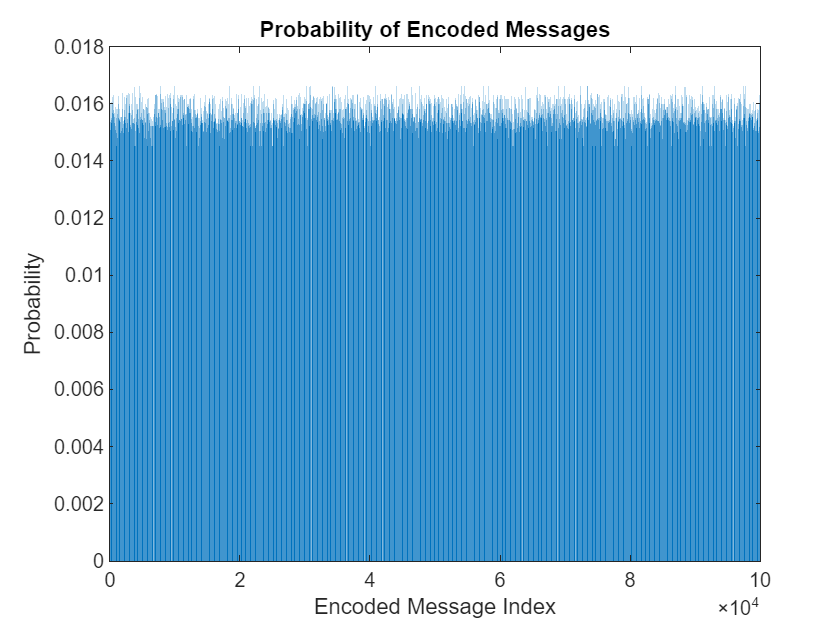

calculate_probabilities_4();

% Μετά την εκτέλεση αυτής θα δούμε ότι όλες οι πιθανότητες είναι κοντά
% στο 0,016 κάτι το οποίο δείχνει ομοιόμορφη κατανομή.

## Ερώτημα 5ο

     0     1     0     0     1     1
     0     0     0     1     0     0
     1     0     0     0     0     0
     1     1     1     1     1     1
     1     0     1     0     1     1
     1     1     1     1     0     0
     0     0     1     0     0     0
     0     1     0     1     1     0
     0     0     0     0     1     0
     1     1     1     0     1     0

     0     0     1     1     1     0
     0     0     1     1     1     0
     1     0     0     1     1     1
     1     1     1     1     0     0
     1     1     0     1     1     1
     1     1     1     1     0     1
     0     1     0     0     1     0
     1     1     1     0     0     0
     1     1     1     1     1     0
     0     1     1     0     1     0

     0     0     0     0     1     1
     0     1     1     0     1     1
     0     0     1     1     1     1
     0     1     0     1     1     1
     0     1     0     1     0     1
     0     0     1     1     0     1
     0     1     1     0     0     0

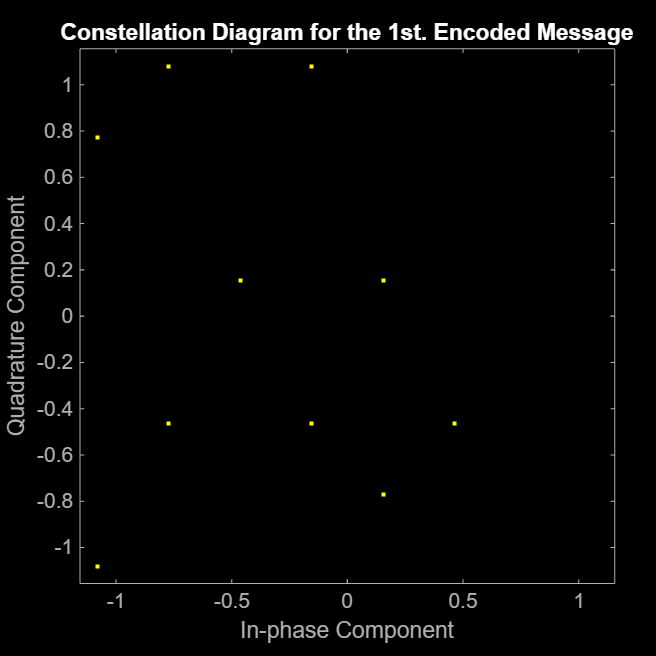

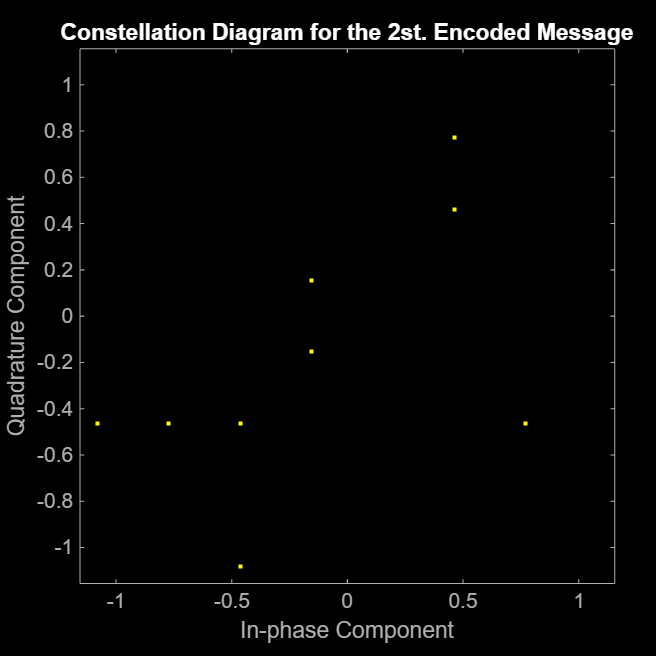

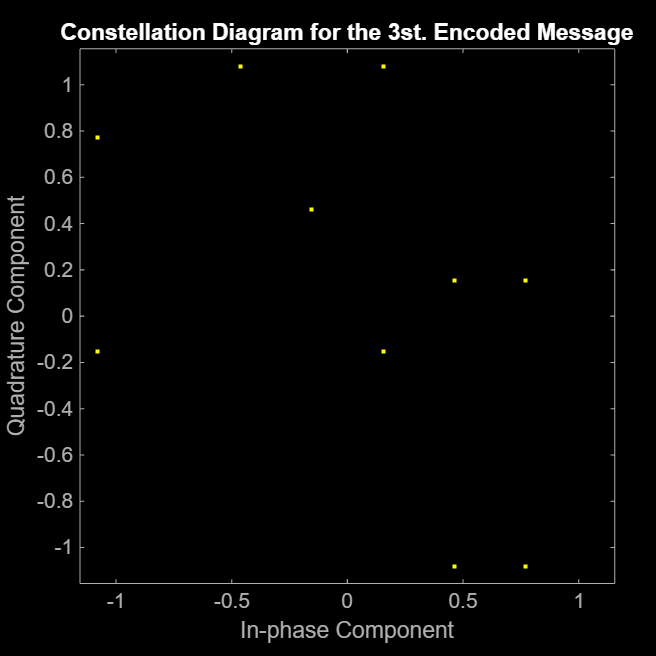

% Δείχνουμε τον αστερισμό για τα πρώτα 3 μηνύματα.
do_QAM64_5(3);

% Γενικά έχουμε έναν πίνακα ο οποίος έχει 100000 μηνύματα και κάθε μύνημα
% είναι σε ομάδες τον 6 bit τα οποία τώρα αναπαριστούνται σαν μυγαδικοί.
% round(56/6) = 10 (προς τα πάνω), άρα 10 columns.

## Ερώτημα 6ο

superpositionCoding_6_new();

## Ερώτημα 7ο

% Τώρα δημιουργούμε ένα Gaussian κανάλι με βάση την εκφώνηση και
% υπολογίζουμε ανάλογα με το SNR που μπαίνει σαν παράμετρο στην συνάρτηση
% την διασπορά. Τα μηνύματα που "περνάω" από το κανάλι είναι αυτά της
% ερώτησης 5, δηλαδή τα διαμοεφωμένα μηνύματα. Γενικά στο τέλος τα
% τελικά μηνύματα τα αποθηκευω σε ένα αρχειό mat, ώστε να τα επεξεργαστώ
% στην συνέχεια.
awgn_channel_7(15);
% Η είσοδος είναι μιγαδικοί και η έξοδος είναι πάλι μιγαδικός

### Για 8 δείτε πιο κάτω

% ...

## Ερώτημα 9

% Τώρα είμαστε στην πλευρά του δέκτη και κάνουμε αποδιαμόρφωση 64-QAM.
do_unQAM64_9(56); % Το μέγεθος των μηνυμάτων αμά δούμε από το ερώτημα 4 είναι 56.
% Σχηματίζω τα κανονικά μηνύματα από τους μιγαδικούς.

## Ερώτημα 10

% Δεν το έκανα

## Ερώτημα 11

apply_hamming_de_coding_11_b();
% Λοιπόν εδω κάνω de-hamming αλλά και διορθώνω τα λάθη. Γενικά έχω
% ακολουθήσει πάλι ακριβώς ότι λέει η διαφάνεια στο eclass. 
% Επίσης το έχω ελέγξει και χειροκίνητα και φαίνεται να δουλέυει σωστά.
% --

#### Ερώτημα 11 (remove πλεονασμό)

% Το επόμενο βήμα είναι να πεταχτουν τα bit πλεονασμού, τα οποία είναι τα
% parity bits (Ε0, Ε1 και Ε2)
% Θυμίζω η δομή των τελευταίων είναι 7-bit --> Π3 Π2 Π1 Ε2 Π0 Ε1 Ε0
% Άρα αυτά που θέλω εγώ να βγάλω είναι στην θέση 4, 6 και 7
% Αρα στη ακόλουθη συνάρτηση ξανα-ομαδοποιώ για κάθε μήνυμα επαναληπτικά τα
% 7-bit για κάθε segment του και βγάζω τα parity. 56/7 = 8.
remove_redundancy_11_c();

#### Ερώτημα 11 (πάλι CRC και συνολικά λάθοι)

% Τώρα θα παμε να ξανακανουμε CRC με βαση το ίδιο πολυώνυμο, 
% καθώς δέκτης και αποστολέας έχουνε συμφωνήσει στο ίδιο. 
% Θα πρέπει να δούμε τα τελευταία bits αν είναι σωστά (όλα 0) ή όχι.
% Γενικά είχα λίγο μπερδευτεί πως ακριβώς βλέπουμε αν υπάρχει λάθος αλλά
% με βοηθήσε το παρακάτω βίντεο.
% https://www.youtube.com/watch?v=6gbkoFciryA
[total_errors, num_messages] = applyCRC_11_d();
X = ['Total num of error: ', num2str(total_errors),'/', num2str(num_messages)];
disp(X); % Θυμίζω ότι αυτό είναι με SNR 15 (δες 7ο)

Total num of error: 98652/100000


#### Ερώτημα 12 και 8

% Τώρα θα δοκιμάσω για διάφορα SNR το PER που λαμβάνω στο κανάλι της Alice
% με Bob (μειούμενο 35dB (καλό καναλι) - 15dB (κακό καναλι))
% Ουσιαστικά θα πρέπει να τρέξουμε τις συναρτήσεις από ερώτημα 7 και μετά.
% !!Ο παρακάτω κώδικας πέρνει πολύ χρόνο!!
% και συνιστάται  να μην τον τρέξετε
% ουσιαστικά δοκιμάζει από 35 εώς 15 τιμές για SNR. Περνά δηλαδή τα
% μηνύματα που δημιουργήθηκαν στο ερώτημα 5 στον αποστολέα μετά την κωδικοποιήση
% 64-QAM από το awgn κανάλι.
% Οπότε οι υπόλοιπες συναρτήσεις που ακολουθούν είναι αυτές που αφορούν τον δέκτη,
% 1) Κάνει απο-κωδικοποιήση 64-QAM
% 2) εφαρμόζει de-hammming (διορθώνει και λάθη)
% 3) και διώχνει τον πλεονασμό
% 4) Μετά πρέπει να μετρηθούν τα λάθοι εφαρμόζοντας CRC (δείτε ερώτημα 11)
% Σημαντικό είναι το δέυτερο κομμάτι το οποίο είναι ακριβώς το ίδιο με την διαδικασία 
% που περιγράφτηκε πριν απλά τώρα αφορά την EVE και με βάση το ερώτημα 8
% αυτή έχε διαφορά 4 SNR άρα άμα το SNR Bob είναι 35 το SNR στην Eve θα
% είναι 35 - 4 = 31 κτλ.

SNR_range = 35:-1:15;
for SNR_dB = SNR_range
    % Bob
    awgn_channel_7(SNR_dB);
    do_unQAM64_9();
    apply_hamming_de_coding_11_b();
    remove_redundancy_11_c();
    
    [total_errors, num_messages] = applyCRC_11_d();
    error_rate_percentage = (total_errors / num_messages) * 100;
    X = ['BOB-SNR:', SNR_dB, ' - Total num of errors: ', num2str(total_errors), '/', num2str(num_messages), ' - ', num2str(error_rate_percentage), '%'];
    disp(X);

    % Eve, σύμφωνα με το ερώτημα 8 θα πρέπει το κανάλι της να είναι
    % χειρότερο, αρά -4 SNR κάθε φορά. 
    SNR_dB_eve = SNR_dB - 4;
    awgn_channel_7(SNR_dB_eve);
    do_unQAM64_9();
    apply_hamming_de_coding_11_b();
    remove_redundancy_11_c();
    
    [total_errors, num_messages] = applyCRC_11_d();
    error_rate_percentage = (total_errors / num_messages) * 100;
    X = ['EVE-SNR:', num2str(SNR_dB_eve), ' - Total num of errors: ', num2str(total_errors), '/', num2str(num_messages), ' - ', num2str(error_rate_percentage), '%'];
    disp(X);
end

#### Στατική δοκιμή (Ερώτημα 12 και 8)

% Σε αυτό το κομμάτι θα κάνω ότι λέω από πάνω απλά για σηγκεκριμένο SNR.
% Bob
SNR_dB = 35;
awgn_channel_7(SNR_dB);

    1.0574

        3163



do_unQAM64_9();
apply_hamming_de_coding_11_b();
remove_redundancy_11_c();

[total_errors, num_messages] = applyCRC_11_d();
error_rate_percentage = (total_errors / num_messages) * 100;
X = ['BOB-SNR:', SNR_dB, ' - Total num of errors: ', num2str(total_errors), '/', num2str(num_messages), ' - ', num2str(error_rate_percentage), '%'];
disp(X);

BOB-SNR:# - Total num of errors: 98435/100000 - 98.435%



% Eve, σύμφωνα με το ερώτημα 8 θα πρέπει το κανάλι της να είναι
% χειρότερο, αρά -4 SNR κάθε φορά. 
SNR_dB_eve = SNR_dB - 4;
awgn_channel_7(SNR_dB_eve);

    1.0574

        1259



do_unQAM64_9();
apply_hamming_de_coding_11_b();
remove_redundancy_11_c();

[total_errors, num_messages] = applyCRC_11_d();
error_rate_percentage = (total_errors / num_messages) * 100;
X = ['EVE-SNR:', num2str(SNR_dB_eve), ' - Total num of errors: ', num2str(total_errors), '/', num2str(num_messages), ' - ', num2str(error_rate_percentage), '%'];
disp(X);

EVE-SNR:31 - Total num of errors: 98435/100000 - 98.435%


% Γενικά τα αποτελέσματα που βλέπουμε είναι πολύ λάθος δεν μπορώ να
% καταλάβω γιατί βγαίνουν τόσο χάλια, έλεγξα και χειροκίντα όλες τις 
% συναρτήσεις που καλόυνται και φαίνεται να δουλεύουν σωστά, δεν μπορώ να
% καταλάβω τι γίνεται λάθος. 
% Επίσης δοκίμασα αντί για την δική μου συνάρτηση για το Gaussian κανάλι
% την συνάρτηση της MATLAB awgn(A, SNR) και είχα ακριβώς τα ίδια
% αποτελέσματα.
% Μια μικρή διαφορά μπορούμε να δούμε αν βάλουμε SNR 15 (κακό κανάλι σε
% σχέση με πριν) παρόλα αυτά πάλι έχουμε PER στο 98%
SNR_dB = 15;
awgn_channel_7(SNR_dB);

    1.0574

    32



do_unQAM64_9();
apply_hamming_de_coding_11_b();
remove_redundancy_11_c();

[total_errors, num_messages] = applyCRC_11_d();
error_rate_percentage = (total_errors / num_messages) * 100;
X = ['BOB-SNR:', num2str(SNR_dB), ' - Total num of errors: ', num2str(total_errors), '/', num2str(num_messages), ' - ', num2str(error_rate_percentage), '%'];
disp(X);

BOB-SNR:15 - Total num of errors: 98694/100000 - 98.694%


% Βλέπουμε ότι και καλά για μικρότερο SNR έχουμε μεγαλύτερο PER (98.694%)
% σε σχέση με πριν που είχαμε SNR 35 (98.435%)
% Γενικά δεν πιστεύω ότι τα αποτελέσματα που έχω βγάλε είναι σωστά αλλά για
% να απαντήσω στην ερώτηση 12 για Eve το μεγαλύτερο SNR που έχω με PER > 98% 
% μπορούμε να πούμε ότι είναι το 35dB, στην EVE το PER είναι παρόμοιο (θα θέλαμε να ήταν παραπάνω 100%
% για να έχει και κάλα πιο κακό κανάλι και περισσότερα λάθοι)

## Ερώτημα 13

% Όπως είπα πριν δεν μπορώ να βγάλω σωστά αποτελέσματα αλλά για να υπάρχει
% μυστικότητα θα πρέπει γενικά το κανάλι της EVE να είναι χειρότερο από
% άποψη ποιότητας. Θα θέλαμε PER σε Alice - Bob όσο πιο μικρό γίνεται και
% Eve όσο πιο μεγάλο γίνεται. Άρα άμα κρίνω από που τα PER που βρήκα πριν,
% που είναι πολύ κοντά το ένα το άλλο και μεγάλα δεν πρέπει να έχουμε μυστικότητα.
% --
% Μια λύση είναι οι LDPC κώδικες που παρέχουν ισχυρή διόρθωση σφαλμάτων, 
% η οποία βελτιώνει την αξιοπιστία της επικοινωνίας για τον Bob, 
% ενώ παράλληλα ενισχύει την ασφάλεια καθιστώντας τη διαδικασία 
% αποκωδικοποίησης του υποκλοπέα πιο δύσκολη (με μεγαλύτερα σφάλματα για Eve).
% Επίσης μια άλλη λύση είναι και η εισαγωγή Artificial Noise στην Eve.
% Σενάριο:
% - Η Alice θέλει να στείλει ένα μήνυμα στον Μπομπ εμποδίζοντας παράλληλα την
% Eve να κατανοήσει το μήνυμα.
% - Η Alice κωδικοποιεί το μήνυμα χρησιμοποιώντας έναν κώδικα LDPC 
% ειδικά σχεδιασμένο για το κανάλι μεταξύ αυτής και του Bob.
% Κατά τη διάρκεια της μετάδοσης, η Alice μπορεί να προσθέσει τεχνητό
% θόρυβο.
% - O Bob ξέροντας ότι χρησιμοποιείται LDPC και Art-Noise τότε μπορεί να 
% αποκωδικοποιείσει το μήνυμα με μεγάλη επιτυχία.
% - Η Eve δεν ξέρει τίποτα από αυτά άρα δυσκολεύεται και έχει και κακό 
% κανάλι οπότε το PER είναι υψηλό.

## Ερώτημα 14

% Αρχικά ορίζουμε τον Hm
Hm = [1.6330 0.4082 - 0.7071*1i 0.4082 + 0.7071*1i ; 1.1547 -0.5774 + 1*1i -0.5774 - 1*1i ; 0 0.7071 - 1.2247*1i -0.7071 - 1.2247*1i]

Hm =    1.6330 + 0.0000i   0.4082 - 0.7071i   0.4082 + 0.7071i
   1.1547 + 0.0000i  -0.5774 + 1.0000i  -0.5774 - 1.0000i
   0.0000 + 0.0000i   0.7071 - 1.2247i  -0.7071 - 1.2247i


% Βλέπουμε 3 κεραίες στην Alice και 3 στον Bob (3x3)

## Ερώτημα 15

% Τώρα πρέπει να αποφασίζουμε αν θα κάνουμε beamforming ή Artificial Noise
% Για αυτό θα πρέπει να υπολογίζουμε τις ιδιάζουσες τιμές.
% Η συνάρτηση που έχουμε παρακάτω  χρησιμοποιεί την συνάρτηση της
% MATLAB η οποία ονομάζεται SVD.
[~, S, ~] = calc_idiazouses(Hm); % εμας μας νοιάζει μόνο ο μεσαίος πίνακας

returns --> [U, S, V] = svd(H);
NOTE: U is a matrix containing the --left singular vectors-- of H
NOTE: S is a diagonal matrix containing the --singular values-- of H
NOTE: V is a matrix containing the --right singular vectors-- of H


S =     2.0000         0         0
         0    2.0000         0
         0         0    1.9999


% Παρατηρούμε ότι οι ιδιοτιμές του είναι πολύ κοντα η μια με την άλλη και καμία 0
% οπότε δεν έχει νόημα να κάνουμε artnoise, για να επιτύχουμε μυστικότητα
% θα κάνουμε beamforming.

## Ερώτημα 16

% Στο MRC στέλνουμε στην κάθε βαθμίδα του
% πομπού το σήμα, και αυτό πολλαπλασιάζεται με τον
% αναστροφοσυζυγή του καναλιού.